# Data smoothing

*Glajenje *podatkov poteka tako, da ustvarimo nek *sliding window *in ga zapolnimo z normalno porazdeljenimi vrednostmi, katerim pravimo **uteži. **Nove vrednosti izračunamo tako, da množimo prvotne vrednosti znotraj obsega *okna *z pripadajočimi utežmi, nato pa izračunamo povprečje vsote vseh novo izračunanih vrednosti.

Skica:

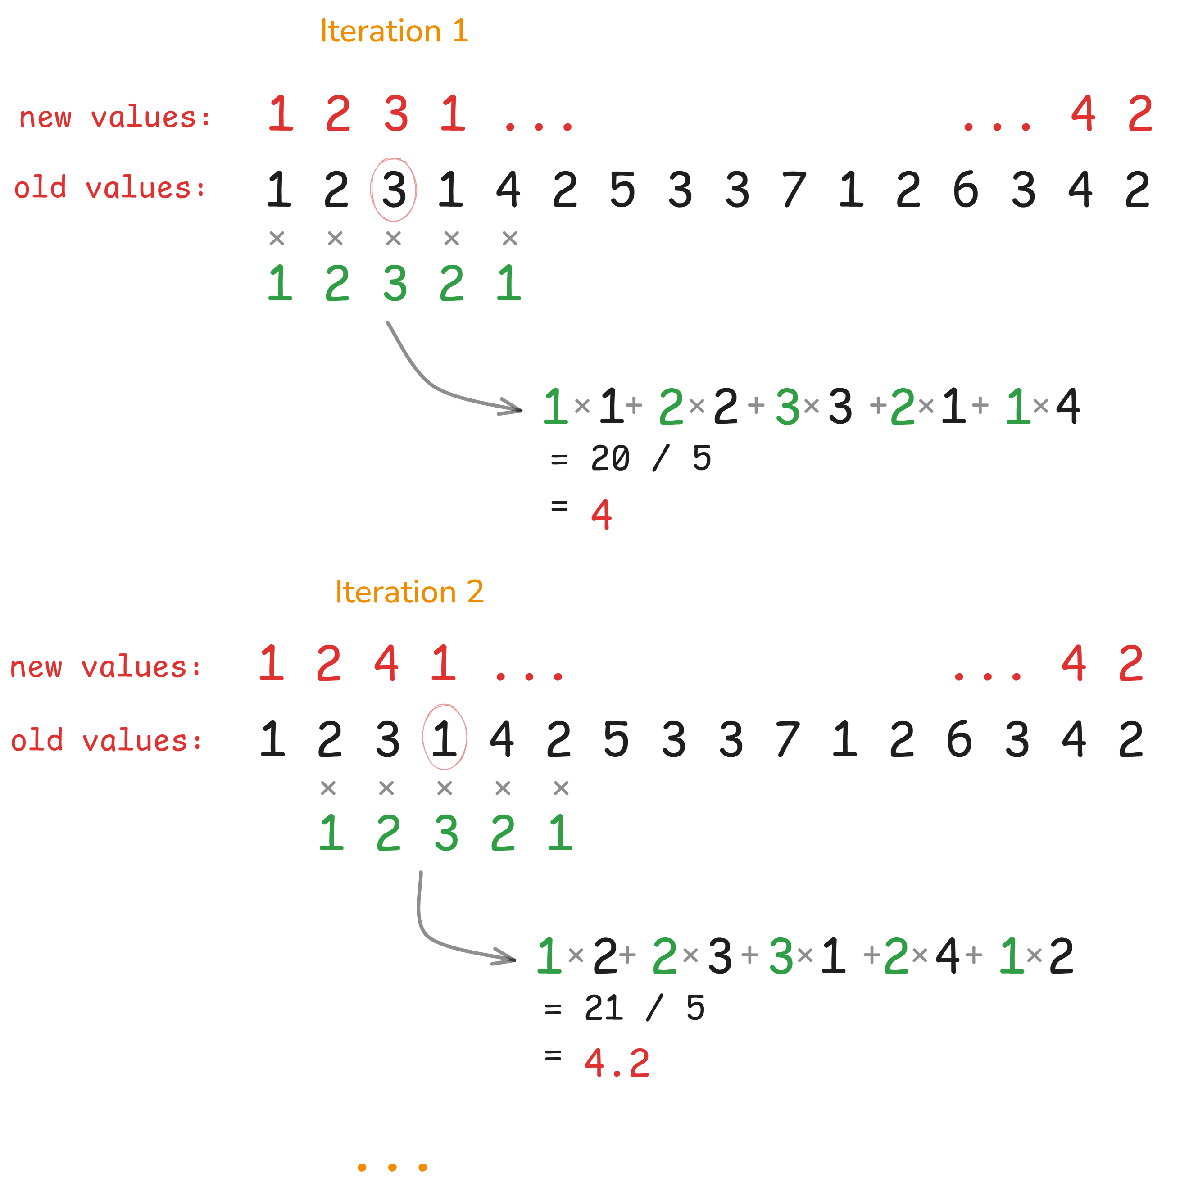

Če imamo okno velikosti 5, začnemo s 3. vrednostjo v seznamu števil, saj mora imeti nova vrednost največjo utež. Zaradi tega prvih dveh (in zadnjih dveh) v tem primeru ne spremenimo.

#### *Write a function in Matlab to smooth data. The function should allow the use of different window  sizes (e.g. 7, 9, 11, 13, …, 31, ...) and the weights should be defined as a Fibonacci sequence  (except zero).*

Funkcija s katero bomo *pogladili *podatke. Algoritem je podoben, kot je predstavljen na skici zgoraj. Namesto prej definiranega vektorja uteži, lahko uporabnik sam določi velikost okna z `ws`. Ustvarjene bodo uteži s pomočjo fibonaccijevega zaporedja. Velikost okna mora biti nad 7 in liho število, zaradi narave metode.

function smoothed_data = pogladkaj(A, ws)
    if ws < 7 || mod(ws, 2) == 0
        fprintf("IllegalArgumentException: window size must be greater than 7 and divisible by 2!\n");
    end
    
    w = zeros(ws, 1);
    n = length(A);
    m = length(w);
    mid = ceil(m/2);
    A_new = zeros(n, 1);
    
    for i = 1:ws
        w(i) = fibonacci(i+1);
    end
    
    for i = mid:n-(mid+1)
        new_A = 0;
    
        for j = 1:m
            if (j == mid)
                w = flip(w);
            end
            
            iter = i - (mid - j);
            cur_w = w(j);
            tmp_A = A(iter);

            new_A = new_A + (tmp_A * cur_w);
        end
        
        w = flip(w);
        A_new(i) = new_A / 5;
    end
    
    smoothed_data = A_new;
end

Preberemo podatke iz datoteke in jo pretvorimo v seznam oziroma `array`. 

data = table2array(readtable("data_unsmoothed.xlsx"));

Ekstrahiramo vrednosti za premik `x` in čas `t`.

x = data(:, 2);
t = data(:, 1);

Izdelati moramo grafe za premik/čas, hitrost/čas ter pospešek/čas. Velja, da je hitrost odvod premika po času ter pospešek odvod hitrosti po času. S pomočjo funkcije `diff` aproksimiramo vrednosti odvoda s pomočjo koraka `df`. Za svoj primer sem izbral okno velikosti 7, a bi delovalo tudi z ostalimi vrednostmi.

dt = t(2) - t(1);
n = length(x);
ws = 7;

Postopoma gladimo podatke in računamo vrednosti za premik, hitrost in pospešek. Stare (nepoglajene) vrednosti so shranjene v seznamih `x, v, a,` nove (poglajene) pa v `x_new, v_new, a_new`.

x_new = pogladkaj(x, ws);

v = diff(x)/dt;
dv = diff(x_new)/dt;
v_new = pogladkaj(dv, ws);

a = diff(v)/dt;
da = diff(v_new)/dt;
a_new = pogladkaj(da, ws);

Preko grafov je razvidno, da so podatki veliko bolj pregledni po glajenju.

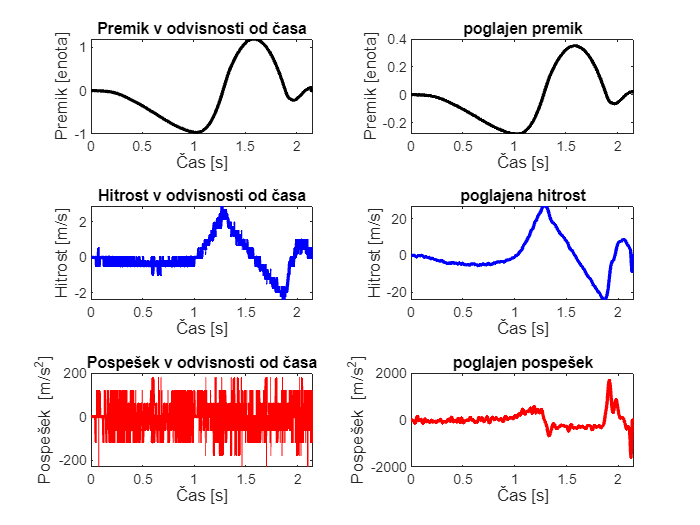

tiledlayout(3, 2);
end_t = length(t)-1; % v in a seznama izgubita vrednost(i)

nexttile
plot(t, x_new, 'k', 'LineWidth', 2)
ylabel('Premik [enota]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('Premik v odvisnosti od časa')

nexttile
plot(t, x, 'k', 'LineWidth', 2)
ylabel('Premik [enota]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('poglajen premik')

nexttile
plot(t(1:end_t), v, 'b', 'LineWidth', 2)
ylabel('Hitrost [m/s]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('Hitrost v odvisnosti od časa')

nexttile
plot(t(1:end_t), v_new, 'b', 'LineWidth', 2)
ylabel('Hitrost [m/s]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('poglajena hitrost')

nexttile
plot(t(1:end_t-1), a, 'r', 'LineWidth', 2)
ylabel('Pospešek [m/s^2]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('Pospešek v odvisnosti od časa')

nexttile
plot(t(1:end_t-1), a_new, 'r', 'LineWidth', 2)
ylabel('Pospešek [m/s^2]','FontSize',10)
xlabel('Čas [s]','FontSize',10)
title('poglajen pospešek')